**Linear regression with multiple variables**

clear all
close all
% Load Data Multi variable data
data = load('USA_Pop_GDP_Inflat.csv');
X = data(:, 1:2); %Example of two variables
y = data(:, 3); %One output 
m = length(y);
% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);
% Add intercept term to X
X = [ones(m, 1) X];
% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1); % Depending on how many variables 
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
3.679836
1.887794
-3.043231

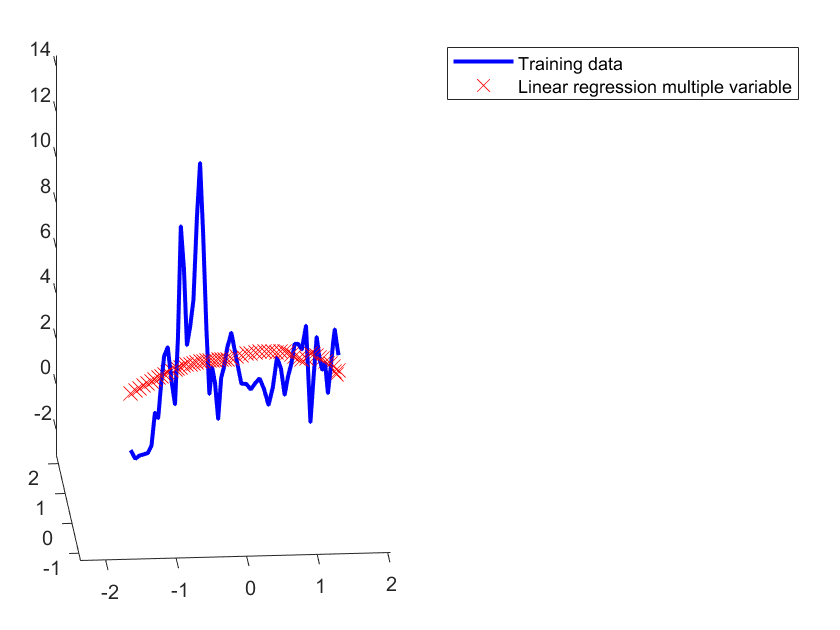


%In case of only two features available
plot3(X(:,2),X(:,3),y,'b-','LineWidth' ,2)
hold on 
plot3(X(:,2),X(:,3),X*theta, 'rx', 'MarkerSize', 10)
hold off % don't overlay any more plots on this figure
legend('Training data','Linear regression multiple variable')

Make prediction

%price = theta(1)+theta(2)*((1650-mu)/sigma)+theta(3)*((3-mu)/sigma);

**Normal Equation**

clear all
% Solve with normal equations:
% Load Data
data = csvread('USA_Pop_GDP_Inflat.csv');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);
% In case variables are for trial and not related Normaliziation
% for normal equation soultion
[X, mu, sigma] = featureNormalize(X);
% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
3.679836
3.477259
-4.632696